# A test case DEM

## Create the DEM

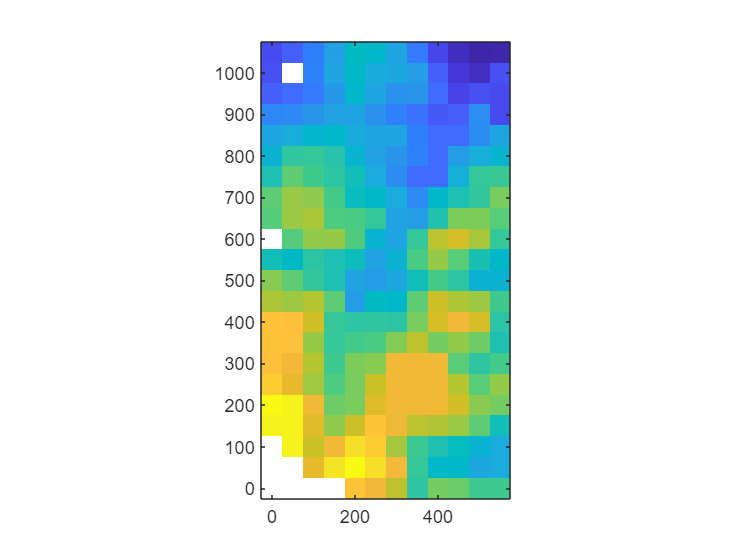

DEM = createTestDEM(100);
figure 
imagesc(DEM)

## Flow directions

### Display flow directions

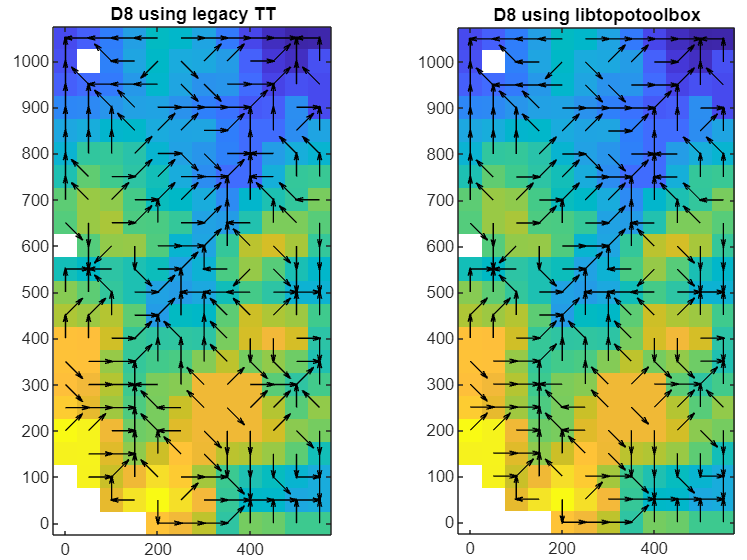

figure
tiledlayout(1,2,"Padding","tight")
FDl = FLOWobj(DEM,"uselibtt", false);
[U,V] = flowvec(FDl);
nexttile
imagesc(DEM)
hold on
[X,Y] = getcoordinates(DEM,'mat');
quiver(X,Y,U.Z,V.Z,0.8,'Color','k')
hold off
title(gca,'D8 using legacy TT')

FDtt = FLOWobj(DEM,"uselibtt", true);
[U,V] = flowvec(FDtt);
nexttile
imagesc(DEM)
hold on
quiver(X,Y,U.Z,V.Z,0.8,'Color','k')
hold off
title(gca,'D8 using libtopotoolbox')

### Compare flow accumulation

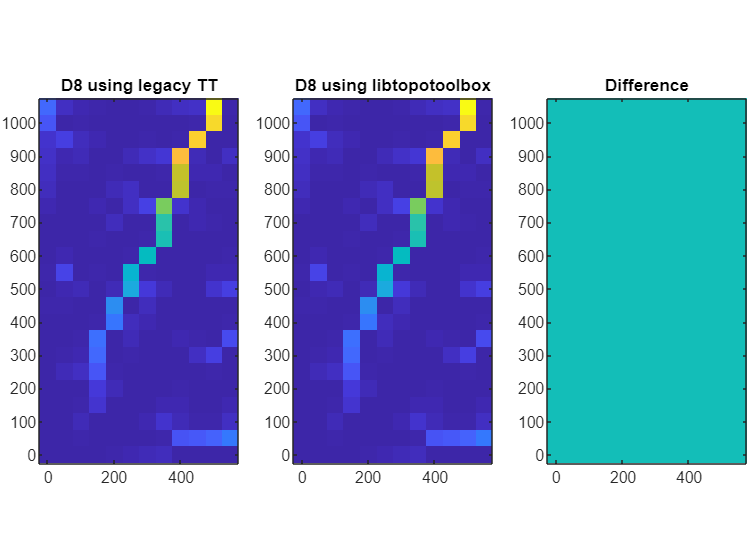

Al  = flowacc(FDl);
Att = flowacc(FDtt);

figure
tiledlayout(1,3,"Padding","tight")
nexttile
imagesc(Al)
title(gca,'D8 using legacy TT')
nexttile
imagesc(Att)
title(gca,'D8 using libtopotoolbox')
nexttile
imagesc(Att-Al)
title(gca,'Difference')